close all, clear all, clc


$$S=\frac{\Delta P}{\Delta z}=\sum_{j=1}^3 \frac{\mu }{\alpha_{\textrm{zj}} \;}u_j +\sum_{j=1}^3 \;c_{2\textrm{zj}} \;\frac{1}{2}\rho |u_j |u_j \;$$


mu = 8.18e-4;           % viscosity; Pa.s
rho = 855.23;           % density; kg/m^3
d_h = 0.007735;         % hydraulic dia; m
dz = 0.476;             % domain length; m
Re = [439, 600, 1270, 1975, 2625, 3341, 4003, 4685, 5382, 6060, 6735, 10170, 13770];
                        % Reynolds no; -;   %## input

DP_x = [16.20, 24.46, 63.07, 114.40, 175.90, 248.30, 329.90, 425.70, 525.30, 641.10,...
        766.8, 1517.00, 2512.00];
DP_c = [14.72, 20.72, 61.53, 113.23, 172.72, 249.96, 332.72, 425.75, 531.53, 647.72,...
        774.17, 1537.63, 2608.35];
DP_a = (DP_x + DP_c)./2;

u_m = Re*mu/(rho*d_h);  % velocity mag; m/serr

**Loop**

for i=1:1:length(u_m)
u = u_m(i).*[0, 0, 1];  % velocity,z; m/s

Let's find the pressure drop due to viscous resistance.


$${\left|\Delta P\;\right|}_{\textrm{vs}} =\left(\sum_{j=1}^3 \frac{\mu }{\alpha_{\textrm{zj}} \;}u_j \right)\Delta z$$


Rv_m = 6;         % viscous resist, mag; 1/m^2, %## input
% Rv_x = 4.0e+8*[1 1 1];
% Rv_y = 4.0e+8*[1 1 1];
Rv_z = Rv_m*1e+5*[1 1 1];   % viscous resist; 1/m^2
alf_z = 1./Rv_z;         % permeability; m^2

This Rv_z is the z-ward acting viscous-R which has 3 componetns [Rv_z1, Rv_z2, Rv_z3] dealing with 3 velocity components (u1, u2, u3) respectively.

  dP_V = mu./alf_z .*u;  % viscous drop; Pa/m
DP_V = sum(dP_V) *dz;       % Pa

Now, let's find the pressure drop due to inertial resistance


$${\left|\Delta P\;\right|}_{\textrm{in}} =\left(\sum_{j=1}^3 \;c_{\textrm{zi}} \;\frac{1}{2}\rho |u_j |u_j \;\right)\Delta z$$


c2_zv = 4.0;                  % head loss; 1/m,   %## input
c2_z = c2_zv*[1 1 1];      

  dP_I = c2_z .*(0.5*rho .*u *norm(u));  % inertial drop, Pa/m
DP_I = sum(dP_I)*dz;          % Pa

Now, let's find the total drop

DP(i) = DP_V + DP_I;      % Pa
end

DP;
er_M = abs(DP - DP_a)./DP_a *100;        % ; %
err = norm(er_M,2);


**Plottings**

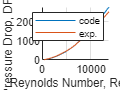

figure(1)
legend, hold on, grid on
plot(Re, DP,   'DisplayName', 'code')
plot(Re, DP_x, 'DisplayName', 'exp.')
% plot(Re, DP_c, 'DisplayName', 'CTF')
hold off
xlabel('Reynolds Number, Re, (-)')
ylabel('Pressure Drop, DP, (Pa)')